clear, clc;
a = 3;
b = 9;
alpha = pi/3;

Ur_a = 0.01;
Ur_b = 0.02;
Ur_alpha = 0.01;

theta = a^2 / (sqrt(b)*sin(alpha))

theta = 3.4641


cr_a = 2

cr_a = 2

cr_b = -1/2

cr_b = -0.5000

cr_alpha = -cos(alpha)/sin(alpha) * alpha

cr_alpha = -0.6046

Ur_theta = Ur_a * abs(cr_a) + Ur_b * abs(cr_b) + Ur_alpha * abs(cr_alpha)

Ur_theta = 0.0360

U_theta = Ur_theta * theta

U_theta = 0.1249


ur_a = Ur_a / sqrt(3);
ur_b = Ur_b / sqrt(3);
ur_alpha = Ur_alpha / sqrt(3);

u_a = ur_a * a;
u_b = ur_b * b;
u_alpha = ur_alpha * alpha;

ur_theta = sqrt((cr_a*ur_a)^2 + (cr_b*ur_b)^2 + (cr_alpha*ur_alpha)^2)

ur_theta = 0.0134

c_a = cr_a * theta / a

c_a = 2.3094

c_b = cr_b * theta / b

c_b = -0.1925

c_alpha = cr_alpha * theta / alpha

c_alpha = -2.0000


u_theta = ur_theta * theta

u_theta = 0.0463

uu_theta = sqrt((c_a*u_a)^2 + (c_b*u_b)^2 + (c_alpha*u_alpha)^2)

uu_theta = 0.0463

clear, clc

g = 9.80665 % valore dell'accelerazione di gravità

alpha_deg = 32; % angolo in gradi
Ur = 0.00045; % incertezza relativa espressa come numero puro
F_kg = 2.5; % forza espressa in kilogrammi-forza
S_ettari = 12; % superficie in ettari
V_cm3 = 52; % volume in centimetri cubici
a = 36; % accelerazione in metri al secondo quadro

alpha = alpha_deg * pi / 180
Ur_pc = Ur * 100
Ur_ppm = Ur * 1e6
F = F_kg * g
S = S_ettari * 1e4
V_ml = V_cm3 * 1e3 % volume in millilitri
a_kmh = a / 1e3 * (3600)^2 % accelerazione in kilometri all'ora quadra

% Il risultato di una misura è:
%     y = -220 km
% e l'incertezza relativa (numero puro) è:
%     Ur = 0.015345

clear, clc
y = -220 % risultato della misura
Ur = 0.015345 % incertezza relativa
U = Ur * abs(y)
Ur_pc = Ur * 100

y_stringa1 = "-220,0" % stesse cifre dopo la virgola di U_stringa
U_stringa = "3,4" % max 2 cifre significative
y_stringa2 = "-220,0" % stesse cifre dopo la virgola di Ur_pc_stringa
Ur_pc_stringa = "1,5" % max 2 cifre significative

%==============================
% Nota
% Si ipotizzi di considerare corrette queste scritture, la prima con
% incertezza assoluta, la seconda con incertezza relativa:
% 1. y = (-220 ± 1,2345) km
% 2. y = -220 km (± 2,3456 %)
%
% In questo esempio, si dovrebbe rispondere:
% ystringa1 = "-220"
% U_stringa = "1,2345"
%
% ystringa2 = "-220"
% Ur_pc_stringa = "2,3456"

% Per una misura indiretta si dispone di un'incertezza di caso peggiore U,
% (probabilità di copertura = 100 %) e di un'incertezza standard u, per cui è
% possibile calcolare l'incertezza estesa:
%
%     U95 = k95 * u
%     U99 = k99 * u
%
% dove k95 e k99 sono i fattori di copertura con probabilità di copertura
% del 95 % e del 99 % rispettivamente. Essi sono calcolati ipotizzando
% distribuzione gaussiana dell'errore di misura
%
% Si chiede:
% 1) il valore dei fattori di copertura
% 2) in tre casi diversi (u1, u2, u3), se essi possono essere usati per
% calcolare l'incertezza estesa; oppure, viceversa, non possono essere
% usati, e si deve usare l'incertezza di caso peggiore.
%
% La risposta alle domande deve essere nel seguente formato:
% U95_1 = 0 % si intende dire "no, il fattore di copertura k95 non si può usare"
% U95_1 = 1 % si intende dire "sì, il fattore di copertura k95 si può usare"

%==============================
% Dati, e codice che li genera (il codice NON VA MAI RIPORTATO NELLA SOLUZIONE)
clear, clc
U = 12 % incertezza di caso peggiore (probabilità di copertura: 100 %)
u1 = 8 % incertezza standard nel caso 1
u2 = 4.9 % incertezza standard nel caso 2
u3 = 0.1 % incertezza standard nel caso 3

kmax1 = U / u1
kmax2 = U / u2
kmax3 = U / u3

k95 = norminv((0.95+1)/2) % fattore di copertura per una probabilità di copertura cp = 95 %
k99 = norminv((0.99+1)/2) % fattore di copertura per una probabilità di copertura cp = 99 %
U95_1 = (kmax1 > k95)
U95_2 = (kmax2 > k95)
U95_3 = (kmax3 > k95)
U99_1 = (kmax1 > k99)
U99_2 = (kmax2 > k99)
U99_3 = (kmax3 > k99)

clear, clc
syms m kg s A K mol
who

% F = q*E => E = F/q [m * kg / (A * s^3)]
% q = int(i dt) [A * s]
% F è in N
% N è in m * kg / s^2
% V = int(E ds) [m^2 * kg / (A * s^3)]

% N = kg * m * s^-2
% L = F * s [J = N * m = kg * m^2 * s^-2]
% P = dL/dt [W = J/s = kg * m^2 * s^-3]
% P = V*i => V = P/i [W/A]
V = kg * m^2 * A^-1 * s^-3

unita_E = kg * m * A^-1 * s^-3
% E * superficie
unita_phi = kg * m^3 * A^-1 * s^-3

% V = Q/C => C = Q/V [A * s / V]
F = A * s * V^-1
% E = q / 4pi*eps*(r^2) => eps = q / 4*pi*E*(r^2) [A * s * m^-2 * V^-1 * m]
% C = eps * S/d => eps = C * d/S [F * m^-1]
unita_epsilon = A * s * m^-2 * V^-1 * m

% Suggerimento: si ricordi che: 
% 1) il flusso di un campo attraverso una superficie è il suo integrale sulla superficie stessa;
% 2) per la capacità vale la legge la legge C = q / V, da cui i = C*dv/dt;
% 3) per un condensatore piano ideale, la capacità è C = epsilon * S / d

% Si deve misurare la distanza di una boa C dalla riva, mediante triangolazione da due punti A e B.
% La misura della distanza c = AB è nota e pari a 50,00 m.
% Gli angoli al punto A (α) e al punto B (β), misurati con un teodolite, sono:
%     α = 35,20°     β = 48,10°

clear, clc
c = 50;              % distanza di base AB (m)
alpha_deg = 35.2;      % angolo al punto A (gradi)
beta_deg = 48.1;           % angolo al punto B (gradi)

alpha = alpha_deg * pi / 180;
beta = beta_deg * pi / 180;

b = sin(beta) * c / sin(pi-alpha-beta)
h = b * sin(alpha)

% x(t) = x0 + v0*t + 1/2*a*t^2

% I parametri incogniti sono:
% theta = [x0; v; a]

clear, clc

N = 20;
t = (0:N-1)'/N;
y = 0.1 + 1.5*t + 1/2*(-2)*t.^2 + randn(N,1)*0.1; 
cp = 0.99;

whos

  Name       Size            Bytes  Class     Attributes

  N          1x1                 8  double              
  cp         1x1                 8  double              
  t         20x1               160  double              
  y         20x1               160  double              




figure
plot(t,y,'o-') % per visualizzare i dati
xlabel('tempo / s')
ylabel('posizione misurata / m')

A = [ones(N,1), t, t.^2/2] % matrice dei regressori, assumendo come vettore dei parametri theta = [x0; v0; a]

A =     1.0000         0         0
    1.0000    0.0500    0.0013
    1.0000    0.1000    0.0050
    1.0000    0.1500    0.0112
    1.0000    0.2000    0.0200
    1.0000    0.2500    0.0312
    1.0000    0.3000    0.0450
    1.0000    0.3500    0.0612
    1.0000    0.4000    0.0800
    1.0000    0.4500    0.1013


C = (A'*A)^-1 * A' % matrice pseudoinversa di A

C =     0.3708    0.2981    0.2318    0.1721    0.1188    0.0721    0.0318   -0.0019   -0.0292   -0.0500   -0.0643   -0.0721   -0.0734   -0.0682   -0.0565   -0.0383   -0.0136    0.0175    0.0552    0.0994
   -1.5195   -1.0998   -0.7234   -0.3903   -0.1005    0.1460    0.3493    0.5092    0.6259    0.6992    0.7293    0.7161    0.6596    0.5598    0.4167    0.2303    0.0007   -0.2723   -0.5885   -0.9481
    2.5974    1.7772    1.0481    0.4101   -0.1367   -0.5924   -0.9569   -1.2303   -1.4126   -1.5038   -1.5038   -1.4126   -1.2303   -0.9569   -0.5924   -0.1367    0.4101    1.0481    1.7772    2.5974


Q = (A'*A)^-1; % matrice gramiana inversa
P = A*C; % matrice proiezione
theta_hat = C * y % vettore dei parametri stimati

theta_hat =     0.1090
    1.6744
   -2.1643


x0_hat = theta_hat(1);
v0_hat = theta_hat(2);
a_hat = theta_hat(3);
x_hat = A * theta_hat; % vettore dei campioni di segnale stimati

hold on;
plot(t,x_hat,'-')

e_hat = y - x_hat

e_hat =     0.0448
    0.1659
   -0.2515
    0.0529
   -0.0087
   -0.1782
   -0.0973
   -0.0257
    0.2922
    0.2061


nu = N - size(theta_hat, 1) % numero di gradi di libertà nella valutazione di tipo A dell'incertezza

nu = 17

u0 = sqrt(sum(e_hat.^2)/nu)

u0 = 0.1534

Sigma_theta = Q * u0^2 % matrice covarianza di tipo A dei parametri stimati theta_hat

Sigma_theta =     0.0087   -0.0357    0.0611
   -0.0357    0.2076   -0.4073
    0.0611   -0.4073    0.8574


u_theta = sqrt(diag(Sigma_theta))% incertezza standard di tipo A dei parametri stimati theta_hat

u_theta =     0.0934
    0.4556
    0.9259


Sigma_x = P * u0^2 % matrice covarianza di tipo A dei campioni di segnale stimati x_hat

Sigma_x =     0.0087    0.0070    0.0055    0.0040    0.0028    0.0017    0.0007   -0.0000   -0.0007   -0.0012   -0.0015   -0.0017   -0.0017   -0.0016   -0.0013   -0.0009   -0.0003    0.0004    0.0013    0.0023
    0.0070    0.0058    0.0046    0.0036    0.0027    0.0018    0.0011    0.0005    0.0000   -0.0004   -0.0007   -0.0009   -0.0010   -0.0010   -0.0009   -0.0006   -0.0003    0.0001    0.0007    0.0013
    0.0055    0.0046    0.0039    0.0032    0.0025    0.0020    0.0015    0.0010    0.0006    0.0003    0.0000   -0.0002   -0.0003   -0.0004   -0.0004   -0.0004   -0.0003   -0.0001    0.0001    0.0004
    0.0040    0.0036    0.0032    0.0028    0.0024    0.0021    0.0017    0.0014    0.0011    0.0009    0.0007    0.0005    0.0003    0.0001   -0.0000   -0.0001   -0.0002   -0.0003   -0.0003   -0.0003
    0.0028    0.0027    0.0025    0.0024    0.0023    0.0021    0.0019    0.0018    0.0016    0.0014    0.0012    0.0010    0.0008    0.0006    0.0004    0.0001   -0.0001   -0.0004   -0.

u_x = sqrt(diag(Sigma_x)) % incertezza standard di tipo A del segnale stimato x_hat

u_x =     0.0934
    0.0760
    0.0622
    0.0527
    0.0475
    0.0460
    0.0469
    0.0487
    0.0504
    0.0514


k = tinv((1+cp)/2, nu)

k = 2.8982

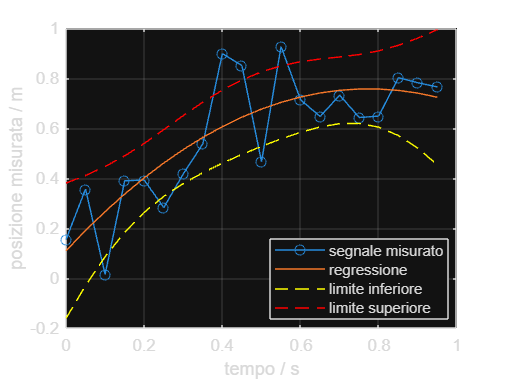

x_U = x_hat + k * u_x; % limite superiore della banda di confidenza con prob. cp per il segnale x
x_L = x_hat - k * u_x; % limite inferiore della banda di confidenza con prob. cp per il segnale x

plot(t, x_L, '--', 'color', 'yellow')
plot(t, x_U, '--', 'color', 'red')
grid on;
legend('segnale misurato', 'regressione', 'limite inferiore', 'limite superiore', 'Location','best')

% Si collega un generatore con resistenza interna Rgen a un filtro
% CR come in figura. Si collegano i due canali dell'oscilloscopio all'ingresso
% e all'uscita del circuito CR.
% Con il circuito si misura sia la risposta al gradino, sia la risposta a
% un segnale sinusoidale (FRF con sinusoide single-tone).

clear, clc
R = 300 % resistenza del circuito (ohm)

R = 300

C = 2e-9 % capacità del circuito (F)

C = 2.0000e-09

s = tf('s') % variabile s della trasformata di Laplace

s =
 
  s
 
Continuous-time transfer function.
Model Properties


f = 3e5 % frequenza del segnale sinusoidale (Hz)

f = 300000

w = 2*pi*f;

% V2 / Vgen = R / (R + Rgen + 1/sC) = RCs / (ReqCs + 1)
% Req = R + Rgen
% V2 / V1 = R / (R + 1/sC) = RCs / (RCs + 1)

Rgen = 50 % resistenza interna del generatore

Rgen = 50

Req = R + Rgen;
tau = R*C;
tau1 = Req*C;
Hdot1 = tau*s / (1 + tau1*s) % funzione di trasferimento misurando la risposta al gradino, calcolata in s

Hdot1 =
 
    6e-07 s
  -----------
  7e-07 s + 1
 
Continuous-time transfer function.
Model Properties


fc1 = 1/(2*pi*tau1) % frequenza di taglio teorica di Hdot1 (Hz)

fc1 = 2.2736e+05

Hdot = tau*s / (1 + tau*s)

Hdot =
 
    6e-07 s
  -----------
  6e-07 s + 1
 
Continuous-time transfer function.
Model Properties


fc = 1/(2*pi*tau) % frequenza di taglio teorica di Hdot (Hz)

fc = 2.6526e+05

H = tau*2*pi*f / sqrt(1 + (tau*2*pi*f)^2) % risposta di ampiezza al segnale sinusoidale, alla frequenza f

H = 0.7492

phiH = pi/2 - atan2(1, tau*2*pi*f) % risposta di fase al segnale sinusoidale, alla frequenza f

phiH = 0.8468

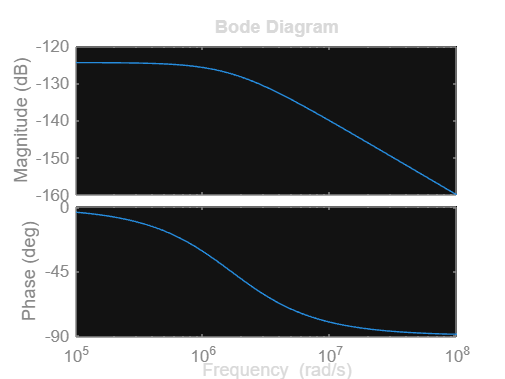

hold off;

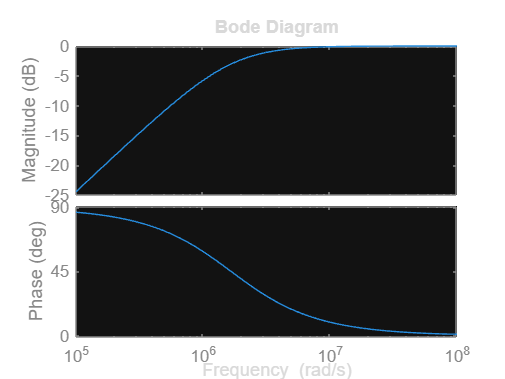

bode(Hdot)

filtro = 2

filtro = 2


%==============================
% Note
% Si consideri se Rgen interviene nella misura, nei due casi (misura di
% risposta al gradino, misura di FRF con sinusoide single-tone).
% Quando si misura la risposta al gradino si utilizza solo la tensione V2
% misurata al canale 2 dell'oscilloscopio, e non si tiene conto di V1.
% Quando si misura la risposta al segnale sinusoidale, si confrontano le
% tensioni V2 e V1.
%
% Suggerimento: calcolare con carta e penna Hdot1 e Hdot, e in base ai calcoli
% rispondere alle domande sulle funzioni di trasferimento.
%
% Per la resistenza Rgen del generatore, utilizzare il valore standard del generatore utilizzato in laboratorio.
%
% Per rispondere alla domanda sul tipo di filtro, usare la seguente codifica:
% filtro = 1 % passa-basso
% filtro = 2 % passa-alto
% filtro = 3 % passa-banda
% filtro = 4 % elimina-banda
% filtro = 5 % passa-tutto

clear, clc
Vpp1 = 6 % tensione picco-picco in ingresso (V)

Vpp1 = 6

Vpp2 = 2.95 % tensione picco-picco in uscita (V)

Vpp2 = 2.9500

R = 250 % resistenza del circuito CR (ohm)

R = 250

f = 3e5 % frequenza della sinusoide (Hz)

f = 300000


Ur_Vpp1 = 1e-3 % incertezza relativa nella misura di Vpp1

Ur_Vpp1 = 1.0000e-03

Ur_Vpp2 = 2e-3 % incertezza relativa nella misura di Vpp2

Ur_Vpp2 = 0.0020

Ur_f = 0.5e-3 % incertezza relativa nella misura di f

Ur_f = 5.0000e-04

Ur_R = 1e-3 % incertezza relativa nella misura di R

Ur_R = 1.0000e-03


%==============================
% Domande
H = Vpp2/Vpp1 % risposta di ampiezza misurata

H = 0.4917

fc = f * (1-H^2)^(1/2)/H % frequenza di taglio misurata dalla risposta di ampiezza

fc = 5.3133e+05

Ur_H = Ur_Vpp1 + Ur_Vpp2 % WCU relativa di H

Ur_H = 0.0030

Ur = [Ur_H; Ur_f] % vettore colonna delle WCU relative di x = [H; f]

Ur =     0.0030
    0.0005



syms h real
fh = sqrt(1 - h^2) / h

$$fh = \frac{\sqrt{1-h^{2}}}{h}$$

dfh = simplify(diff(fh) * h / fh)

$$dfh = \frac{1}{h^{2}-1}$$


Cr = [1 / (H^2 - 1), 1] % matrice dei coefficienti relativi di sensibilità di fc rispetto a x = [H; f]

Cr =    -1.3188    1.0000


Ur_fc = abs(Cr) * Ur % WCU relativa di fc

Ur_fc = 0.0045

ur_H = sqrt(Ur_Vpp1^2 + Ur_Vpp2^2)/sqrt(3) % incertezza standard relativa di H

ur_H = 0.0013

ur_f = Ur_f/sqrt(3)

ur_f = 2.8868e-04

ur = [ur_H; ur_f] % vettore colonna delle incertezze standard relative di x = [H; f]

ur =     0.0013
    0.0003


ur_fc = sqrt(Cr.^2 * ur.^2) % incertezza standard relativa di fc

ur_fc = 0.0017

CH = 1 / (2*pi*fc*R) % capacità del circuito CR misurata dalla risposta di ampiezza H

CH = 1.1982e-09

Ur_CH = Ur_f + Ur_R % WCU relativa nella misura di CH

Ur_CH = 0.0015

ur_CH = sqrt(ur_fc^2 + Ur_R^2/3) % incertezza standard relativa nella misura di CH

ur_CH = 0.0018

% Nota:
% Fare riferimento ai dati "1 Year". La specifica sulla temperatura è da ignorare 
% (temperatura compresa tra 18 e 28 °C).

clear, clc
V = -11.5 % valore di tensione continua misurato (V)

V = -11.5000


VFS = 100

VFS = 100

Ur_reading_pc = 0.0045 % "reading error percentuale": il numero scritto nelle specifiche

Ur_reading_pc = 0.0045

U_range_pcFS = 0.0006% "range error in percentuale del fondo scala": il numero scritto nelle specifiche

U_range_pcFS = 6.0000e-04

U_reading = Ur_reading_pc/100 * abs(V) % "reading error" assoluto (incertezza assoluta dovuta al reading error)

U_reading = 5.1750e-04

U_range = U_range_pcFS/100 * VFS % "range error" assoluto (incertezza assoluta dovuta al range error)

U_range = 6.0000e-04

U_V = U_reading + U_range % incertezza assoluta totale

U_V = 0.0011